% Start timing
tic;

clear;
close all;
clc;

% Define the input parameters for each combination of date, rot_rate, ampl_value, and corresponding start and end frames
input_parameters = {
    '10', 0, 3, 170, 350;
    '10', 0, 5, 170, 350;
    '10', 0, 7, 170, 325;
    '10', 0, 9, 200, 350;
    '10', 0.0524, 3, 170, 300;
    '10', 0.0524, 5, 170, 300;
    '10', 0.0524, 7, 170, 300;
    '10', 0.0524, 9, 200, 350;
    '09', 0.1047, 3, 170, 375;   % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
    '09', 0.1047, 5, 150, 300;   % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
    '09', 0.1047, 7, 170, 350;   % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
    '09', 0.1047, 9, 170, 350;   % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
    '10', 0.2094, 3, 200, 400;   % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
    '10', 0.2094, 5, 170, 300;   % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
    '10', 0.2094, 7, 170, 350;   % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
    '10', 0.2094, 9, 170, 300;   % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
    '09', 0.4189, 3, 200, 400;   % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
    '09', 0.4189, 5, 170, 350;   % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
    '09', 0.4189, 7, 170, 350;   % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
    '09', 0.4189, 9, 200, 350;   % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
    '09', 0.8378, 3, 170, 350;   % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
    '09', 0.8378, 5, 170, 350;   % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
    '09', 0.8378, 7, 170, 350;   % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
    '09', 0.8378, 9, 170, 350;   % Format: 'date', rot_rate, ampl_value, start_frame, end_frame
    % Add the rest of your combinations, e.g., with ampl_value = 5, 7, 9
};
%% Define frequency value (assuming it stays constant)
freq_value = 2.2;
freq_value = string(freq_value);

% Initialize a table to store results
results = table('Size', [0 5], 'VariableTypes', {'string', 'double', 'double', 'double', 'double'}, ...
                'VariableNames', {'Date', 'RotRate', 'AmplValue', 'RMS_Amplitude', 'Standard_Error'});

% Loop through all the input parameter combinations
for i = 1:size(input_parameters, 1)
    date = input_parameters{i, 1};
    rot_rate = input_parameters{i, 2};
    ampl_value = input_parameters{i, 3};
    start_frame = input_parameters{i, 4};
    end_frame = input_parameters{i, 5};

    % Define the base directory for input and output files
    input_dir = sprintf('D:\\Matlab\\Matlab input\\202409%s_full_plate_final\\202409%s_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\', ...
                        date, date, string(rot_rate), freq_value, string(ampl_value));

    % Define the base file name and extension
    base_file_name = sprintf('202409%s_%sradps_%sHz_%smm_full_plate_frame_', date, string(rot_rate), string(freq_value), string(ampl_value));
    file_extension = 'A_vel_new.dat';
    
    % Initialize array to store slopes for each frame
    slopes_over_time = zeros(end_frame - start_frame + 1, 1);
    
    % Iterate over each frame to calculate the slope for the selected long axis point
    for frame_num = start_frame:end_frame
        % Construct the file name for the current frame
        frame_str = sprintf('%04d', frame_num);
        file_name = [base_file_name, frame_str, file_extension];
        input_file = fullfile(input_dir, file_name);

        % Load the data
        dr = loadvec(input_file);

        % Process the data: remove rows and columns with only zeros
        dr_new = dr;
        dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
        dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
        dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
        dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
        dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
        dr_new.vy(all(dr_new.vy == 0, 2), :) = [];

        % Compute the surface height
        h_0 = 150; % surface-pattern distance in mm
        h = surfheight(dr_new, h_0);
        surface_height = h.w;

        % Surface height on short axis for the selected long axis point
        surf_height_short_axis = surface_height(selected_long_axis_point, :);
        ampl_short_axis = surf_height_short_axis;
        values_short_axis = h.y / 10;  % Convert to cm

        % Linear fit for slope calculation
        p = polyfit(values_short_axis, ampl_short_axis, 1);  
        slopes_over_time(frame_num - start_frame + 1) = p(1);  % Store the slope
    end

    % Calculate RMS amplitude and standard error for this combination
    rms_amplitude = sqrt(mean(slopes_over_time.^2));  % RMS amplitude
    standard_error = std(slopes_over_time) / sqrt(length(slopes_over_time));  % Standard error

    % Store the results in the table
    new_row = {date, rot_rate, ampl_value, rms_amplitude, standard_error};
    results = [results; new_row];
end

% Save the table to a CSV file
output_dir = 'D:\Matlab\Matlab output\RMS_Results\';  % Desired folder for saving
if ~exist(output_dir, 'dir')
   mkdir(output_dir);
end

output_file = fullfile(output_dir, 'RMS_Amplitude_and_Standard_Error_Results.csv');
writetable(results, output_file);

toc;

% Start timing
tic;

clear;
close all;
clc;

%% Define rotation rates and corresponding dates
rotation_rates = [0, 0.0524, 0.1047, 0.2094, 0.4189, 0.8378];
dates = {'10', '10', '09', '10', '09', '09'};  % Corresponding dates

%% Define amplitude values
amplitudes = [3, 5, 7, 9];  % Different amplitude values

%% Define frequency value (assuming it stays constant)
freq_value = 2.2;
freq_value = string(freq_value);

%% Define other parameters
start_frame = 200;  % Start frame for time mode
end_frame = 300;    % End frame for time mode
frame_rate = 23.98; % Frame rate in frames per second
h_0 = 150;  % Surface-pattern distance in mm
selected_long_axis_point = 170;  % Point for slope analysis

%% Initialize table to store results
results = table('Size', [0 5], ...
                'VariableTypes', {'double', 'string', 'double', 'double', 'double'}, ...
                'VariableNames', {'RotationRate', 'Date', 'Amplitude', 'RMSAmplitude', 'StandardError'});

%% Loop through all combinations of rotation rates, dates, and amplitudes
for i = 1:length(rotation_rates)
    rot_rate = rotation_rates(i);
    date = dates{i};
    rot_rate_str = string(rot_rate);  % Convert to string

    for ampl_value = amplitudes
        % Convert amplitude value to string for file naming
        ampl_value_str = string(ampl_value);

        % Define the input directory and base file name for this combination
        input_dir = sprintf('D:\\Matlab\\Matlab input\\202409%s_full_plate_final\\202409%s_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\', date, date, rot_rate_str, freq_value, ampl_value_str);
        base_file_name = sprintf('202409%s_%sradps_%sHz_%smm_full_plate_frame_', date, rot_rate_str, freq_value, ampl_value_str);
        file_extension = 'A_vel_new.dat';

        % Initialize an array to store slopes over time for this combination
        slopes_over_time = zeros(end_frame - start_frame + 1, 1);

        %% Loop through frames and calculate slopes over time
        for frame_num = start_frame:end_frame
            % Construct the file name for the current frame
            frame_str = sprintf('%04d', frame_num);
            file_name = [base_file_name, frame_str, file_extension];
            input_file = fullfile(input_dir, file_name);

            % Load the data
            dr = loadvec(input_file);

            % Process the data: remove rows and columns with only zeros
            dr_new = dr;
            dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
            dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
            dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
            dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
            dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
            dr_new.vy(all(dr_new.vy == 0, 2), :) = [];

            % Compute the surface height
            h = surfheight(dr_new, h_0);
            surface_height = h.w;

            % Get the surface height over the short axis for the selected long axis point
            surf_height_short_axis = surface_height(selected_long_axis_point, :);
            ampl_short_axis = surf_height_short_axis;
            values_short_axis = h.y / 10;  % Convert to cm

            % Linear fit for slope calculation
            p = polyfit(values_short_axis, ampl_short_axis, 1);  
            slopes_over_time(frame_num - start_frame + 1) = p(1);  % Store the slope
        end

        %% Calculate RMS Amplitude
        rms_amplitude = rms(slopes_over_time);  % Root Mean Square of the slopes

        %% Calculate Standard Deviation and Standard Error of RMS
        slope_std_dev = std(slopes_over_time);  % Standard deviation of slope values
        N = length(slopes_over_time);           % Number of frames
        standard_error_rms = slope_std_dev / sqrt(N);  % Standard error of RMS amplitude

        %% Append results to the table
        results = [results; {rot_rate, date, ampl_value, rms_amplitude, standard_error_rms}];
    end
end

%% Display the table
disp(results);

%% Save the table to a file
output_file = 'RMS_Amplitude_and_Standard_Error_Results_full.csv';
writetable(results, output_file);

toc;


pwd

ans = 'D:\'

%% Script 1: Slope Across Long Axis for a Specific Frame
tic;

clear 
close all
clc

%% Parameters
date = '10';
rot_rate = 0.2094;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);
ampl_value = 3;

% Define the base directory for input and output files
input_dir = sprintf('D:\\Matlab\\Matlab input\\202409%s_full_plate_final\\202409%s_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\', date, date, rot_rate, freq_value, string(ampl_value));
output_dir = sprintf('D:\\Matlab\\Matlab output\\202409%s_full_plate_final_results\\202409%s_%sradps_%sHz_%smm_full_plate\\Trend\\', date, date, rot_rate, freq_value, string(ampl_value));

% Define the base file name and extension
base_file_name = sprintf('202409%s_%sradps_%sHz_%smm_full_plate_frame_', date, rot_rate, freq_value, string(ampl_value));
file_extension = 'A_vel_new.dat';

%% Parameters specific to 'long_axis' mode
frame_num = 260;  % Frame number for slope calculation across long axis

%% Construct the file name for the specified frame
frame_str = sprintf('%04d', frame_num);
file_name = [base_file_name, frame_str, file_extension];
input_file = fullfile(input_dir, file_name);

%% Load the data
dr = loadvec(input_file);

%% Process the data: remove rows and columns with only zeros
dr_new = dr;
dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vy(all(dr_new.vy == 0, 2), :) = [];

%% Compute the surface height
h_0 = 150; % Surface-pattern distance in mm
h = surfheight(dr_new, h_0);
surface_height = h.w;

%% Initialize array to store slopes along the long axis
num_long_axis_points = size(surface_height, 1);
slopes = zeros(num_long_axis_points, 1);

%% Calculate slopes along the short axis for each long axis point
for i = 1:num_long_axis_points
    surf_height_short_axis = surface_height(i, :);
    ampl_short_axis = surf_height_short_axis;
    values_short_axis = h.y / 10;  % Convert to cm

    % Linear fit for slope calculation
    p = polyfit(values_short_axis, ampl_short_axis, 1);  
    slopes(i) = p(1);  % Store the slope
end

%% Plot slopes over long axis points
values_long_axis = h.x / 10;  % Convert to cm
plot(values_long_axis, slopes, 'b', 'LineWidth', 2);
title(sprintf('Slope over long axis for frame %d', frame_num));
xlabel('Position on long axis (cm)');
ylabel('Slope of surface height');
grid on;

%% Save the plot
saveas(gcf, fullfile(output_dir, sprintf('202409%s_%sradps_%sHz_%smm_slope_vs_long_axis_%s.png', date, rot_rate, freq_value, string(ampl_value), string(frame_num))));

toc;

%% Script 2: Slope Over Time at a Specific Long Axis Point
tic;

clear 
close all
clc

%% Parameters
date = '09';
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);
ampl_value = 7;

% Define the base directory for input and output files
input_dir = sprintf('D:\\Matlab\\Matlab input\\202409%s_full_plate_final\\202409%s_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\', date, date, rot_rate, freq_value, string(ampl_value));
output_dir = sprintf('D:\\Matlab\\Matlab output\\202409%s_full_plate_final_results\\202409%s_%sradps_%sHz_%smm_full_plate\\Trend\\', date, date, rot_rate, freq_value, string(ampl_value));

% Define the base file name and extension
base_file_name = sprintf('202409%s_%sradps_%sHz_%smm_full_plate_frame_', date, rot_rate, freq_value, string(ampl_value));
file_extension = 'A_vel_new.dat';

%% Parameters specific to 'time' mode
selected_long_axis_point = 170;  % Point on long axis to monitor over time
start_frame = 170;  % Start frame number
end_frame = 350;    % End frame number
frame_rate = 23.98;  % Frame rate in frames per second

%% Initialize array to store slopes for each frame
slopes_over_time = zeros(end_frame - start_frame + 1, 1);

%% Calculate time in seconds for each frame
frame_numbers = start_frame:end_frame;
time_in_seconds = (frame_numbers - 1) / frame_rate;

%% Iterate over each frame to calculate the slope for the selected long axis point
for frame_num = start_frame:end_frame
    % Construct the file name for the current frame
    frame_str = sprintf('%04d', frame_num);
    file_name = [base_file_name, frame_str, file_extension];
    input_file = fullfile(input_dir, file_name);

    % Load the data
    dr = loadvec(input_file);

    % Process the data: remove rows and columns with only zeros
    dr_new = dr;
    dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
    dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
    dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
    dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
    dr_new.vy(all(dr_new.vy == 0, 2), :) = [];

    % Compute the surface height
    h_0 = 150; % Surface-pattern distance in mm
    h = surfheight(dr_new, h_0);
    surface_height = h.w;

    % Surface height on short axis for the selected long axis point
    surf_height_short_axis = surface_height(selected_long_axis_point, :);
    ampl_short_axis = surf_height_short_axis;
    values_short_axis = h.y / 10;  % Convert to cm

    % Linear fit for slope calculation
    p = polyfit(values_short_axis, ampl_short_axis, 1);  
    slopes_over_time(frame_num - start_frame + 1) = p(1);  % Store the slope
end

%% Plot slopes over time (in seconds)
plot(time_in_seconds, slopes_over_time, 'b', 'LineWidth', 2);
title(sprintf('Slope of surface height %sradps %sHz %smm pos %d', rot_rate, freq_value, string(ampl_value), selected_long_axis_point));
xlabel('Time (seconds)');
ylabel('Slope of surface height');
grid on;

%% Compute Peak-to-Peak Amplitude
max_slope = max(slopes_over_time);  % Maximum slope value
min_slope = min(slopes_over_time);  % Minimum slope value
peak_to_peak_amplitude = max_slope - min_slope;
fprintf('Peak-to-Peak Amplitude: %.4f\n', peak_to_peak_amplitude);

Peak-to-Peak Amplitude: 0.0890



%% Compute RMS Amplitude
rms_amplitude = rms(slopes_over_time);  % Root Mean Square of the slopes
%% Compute Standard Deviation of Slopes
slope_std_dev = std(slopes_over_time);  % Standard deviation of slope values

%% Compute Standard Error of RMS (SERMS)
N = length(slopes_over_time);  % Number of frames
serms = slope_std_dev / sqrt(N);  % Standard error of the RMS amplitude

%% Display the values
fprintf('RMS Amplitude: %.4f\n', rms_amplitude);

RMS Amplitude: 0.0217


fprintf('Standard Deviation of Slopes: %.4f\n', slope_std_dev);

Standard Deviation of Slopes: 0.0218


fprintf('Standard Error of RMS Amplitude (SERMS): %.4f\n', serms);

Standard Error of RMS Amplitude (SERMS): 0.0016


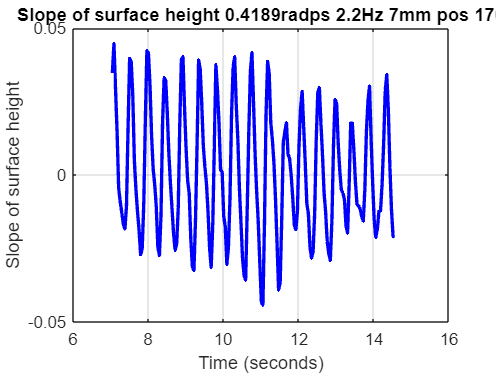


%% Save the plot
saveas(gcf, fullfile(output_dir, sprintf('%sradps_%sHz_%smm_pos_%d_slope_over_time.png', rot_rate, freq_value, string(ampl_value), selected_long_axis_point)));


toc;

Elapsed time is 594.359816 seconds.


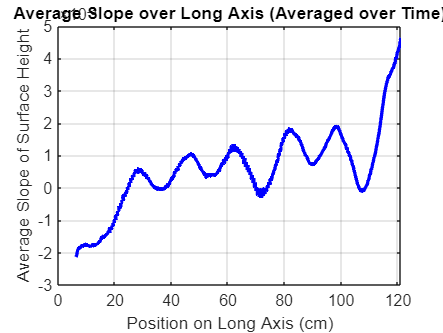

% To plot the average slope (averaged out over time/all the frames) as a
% function of the long axis location

tic;

clear 
close all
clc

%% Parameters
ampl_value = 7;
rot_rate = 0.4189;
rot_rate = string(rot_rate);
freq_value = 2.2;
freq_value = string(freq_value);

% Define the base directory for input and output files
input_dir = sprintf('D:\\Matlab\\Matlab input\\20240909_full_plate_final\\20240909_%sradps_%sHz_%smm_full_plate_separate_frames\\Results\\', rot_rate, freq_value, string(ampl_value));
output_dir = sprintf('D:\\Matlab\\Matlab output\\20240909_full_plate_final_results\\20240909_%sradps_%sHz_%smm_full_plate\\Trend\\', rot_rate, freq_value, string(ampl_value));

% Define the base file name and extension
base_file_name = sprintf('20240909_%sradps_%sHz_%smm_full_plate_frame_', rot_rate, freq_value, string(ampl_value));
file_extension = 'A_vel_new.dat';

%% Common Parameters
start_frame = 190;  % Start of frame number for time mode
end_frame = 350;  % End of frame number for time mode
frame_rate = 23.98;  % Frame rate in frames per second

%% Initialize for Averaging Slopes Over Time
% First, we'll compute the slopes for each frame and each long axis point
% Then, we'll average them over time
first_frame_str = sprintf('%04d', start_frame);
first_file_name = [base_file_name, first_frame_str, file_extension];
first_input_file = fullfile(input_dir, first_file_name);

% Load the first frame data to get the dimensions
dr_first = loadvec(first_input_file);
dr_first.x(:, all(dr_first.vy == 0, 2)) = [];
dr_first.y(:, all(dr_first.vy == 0, 1)) = [];
dr_first.vx(:, all(dr_first.vx == 0, 1)) = [];
dr_first.vx(all(dr_first.vx == 0, 2), :) = [];
dr_first.vy(:, all(dr_first.vy == 0, 1)) = [];
dr_first.vy(all(dr_first.vy == 0, 2), :) = [];

% Compute the surface height for the first frame to get the size
h_0 = 150; % surface-pattern distance in mm
h_first = surfheight(dr_first, h_0);
surface_height_first = h_first.w;

% Number of points along the long axis and short axis
num_long_axis_points = size(surface_height_first, 1);
num_short_axis_points = size(surface_height_first, 2);

% Initialize a matrix to accumulate the slopes for each point along the long axis
slope_accumulator = zeros(num_long_axis_points, end_frame - start_frame + 1);

%% Iterate over frames to calculate slopes for each long axis point
for frame_num = start_frame:end_frame
    % Construct the file name for the current frame
    frame_str = sprintf('%04d', frame_num);
    file_name = [base_file_name, frame_str, file_extension];
    input_file = fullfile(input_dir, file_name);

    % Load the data for the current frame
    dr = loadvec(input_file);

    % Process the data: remove rows and columns with only zeros
    dr.x(:, all(dr.vy == 0, 2)) = [];
    dr.y(:, all(dr.vy == 0, 1)) = [];
    dr.vx(:, all(dr.vx == 0, 1)) = [];
    dr.vx(all(dr.vx == 0, 2), :) = [];
    dr.vy(:, all(dr.vy == 0, 1)) = [];
    dr.vy(all(dr.vy == 0, 2), :) = [];

    % Compute the surface height for this frame
    h = surfheight(dr, h_0);
    surface_height = h.w;

    % Calculate the slope along the short axis for each long axis point
    for i = 1:num_long_axis_points
        surf_height_short_axis = surface_height(i, :);
        ampl_short_axis = surf_height_short_axis;
        values_short_axis = h.y / 10;  % Convert to cm
        
        % Linear fit for slope calculation
        p = polyfit(values_short_axis, ampl_short_axis, 1);  
        slope_accumulator(i, frame_num - start_frame + 1) = p(1);  % Store the slope for this frame
    end
end

%% Calculate the average slope over time for each long axis point
average_slope = mean(slope_accumulator, 2);

%% Plot the average slope over the long axis
values_long_axis = h.x / 10;  % Convert to cm
plot(values_long_axis, average_slope, 'b', 'LineWidth', 2);
title('Average Slope over Long Axis (Averaged over Time)');
xlabel('Position on Long Axis (cm)');
ylabel('Average Slope of Surface Height');
grid on;

% Save the plot
saveas(gcf, fullfile(output_dir, sprintf('average_%d_to_%d_slope_vs_long_axis.png',start_frame,end_frame)));


toc;

% % Surface height on short axis
% % Plot the amplitude/surface height over the short axis
% surf_height_short_axis = surface_height(170,:);
% ampl_short_axis = surf_height_short_axis;
% values_short_axis = h.y/10; % in cm
% plot(values_short_axis,surf_height_short_axis)
% title('Surface height over short axis')
% xlabel('Position on short axis (cm)')
% ylabel('Surface height (mm)')
% 
% p = polyfit(values_short_axis, ampl_short_axis, 1);  % Degree 1 for a linear trend
% trendline = polyval(p, values_short_axis);           % Compute the trendline
% plot(values_short_axis, ampl_short_axis, 'b');       % Plot original data
% hold on;
% plot(values_short_axis, trendline, 'r', 'LineWidth', 2);  % Plot the trendline
% hold off;
% slope = p(1)



% output_file_png_surf_height_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_surf_height_short_axis_%s.png',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% exportgraphics(gcf, output_file_png_surf_height_short);
% output_file_fig_surf_height_short = fullfile(output_dir, sprintf('20240909_%sradps_%sHz_%smm_full_plate_surf_height_short_axis_%s.fig',rot_rate,freq_value,string(ampl_value), string(frame_num)));
% savefig(gcf, output_file_fig_surf_height_short);

